
%%Clearing
clear;


%%Load data
load('dataset/control.dat');
radar = load('dataset/radar1.dat');


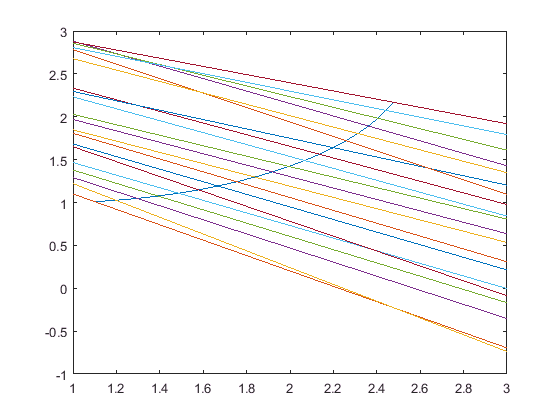

%%Plot schematics

figure
plot(control(1:20,1), control(1:20,2))
for i = 1 : 20
    hold on
    y = radar(i) * (1:3) + (control(i,2) - radar(i)*control(i,1));
    plot(1:3,y)
end

## define our meta-variables

duration = 10  %duration of the experiment

duration = 10

dt = .1;  %The time interval between two measurements



## Coefficent matrices

A = [1 0 dt 0; 0 1 0 dt; 0 0 1 0; 0 0 0 1]; % state transition matrix:  expected trajecory of the Obstacle
% no input control matrix (B)
% no measurement matrix (C), because it's a non-linear equation


## define main variables

n=4;      %number of state
X = [0; 0; 1; 1]; %initized state--it has four components: [posX; posY; velX; velX] of the Obstacle
X_estimate = X;  %x_estimate of initial location estimation of where the Obstacle is (what we are updating)
q=0.1;    %std of process 
r=0.1;    %std of measurement
Q=q^2*eye(n); % covariance of process
R=r^2;        % covariance of measurement
P = Ex; % estimate of initial Quail position variance (covariance matrix)

Undefined function or variable 'Ex'.

## Jacobian

jacobian(-atan(( control(1,1) - x ) / ( control(1,2) - y )  ), [x, y]);

